%constant
c=60;
round=60;
l_veh=7;

E1=9;
E2=13;
E3=5;

%discrete green light time set

u_options=[15,20,25,30,35,40,45];
% u_options=15:1:45;

%algorithm settins
generation_round=300;
member_number=100;
%the exchange_position of parents
exchange_position=20;
%mutation probabilitTTS
mutation_probability=0.2;
%parents_number
parents_number=20

parents_number = 20


%initial generation 0
% u_generation=randi(length(u_options),[1,round]);
u_generation=4*ones(member_number,round);
% u0_generation=randi(length(u_options),[member_number,1])
% for i =2:1:member_number
%     u_generation=[u_generation;randi(length(u_options),[1,round])];
% end

% for i=1:1:length(u_options)
% %     if(i~=4)
%         u_generation(i,:)=i*ones(1,round);
%         u0_generation(i)=i; 
% %     end
% end
for i=1:1:member_number
    for j=1:1:round
       poss=rand(1);
       if (poss<=0.2)
           u_generation(i,j)=randi(length(u_options),1);
       end
    end
end

u_generation

u_generation =      7     6     4     4     2     4     4     4     4     4     4     4     4     7     3     1     4     4     4     4     4     2     4     4     4     6     4     7     4     5     4     4     4     4     4     4     5     4     4     4     4     4     4     4     4     2     4     4     2     4
     3     4     4     5     6     4     3     4     4     4     4     4     3     4     4     4     4     4     4     1     6     4     4     4     4     4     6     4     2     4     4     4     4     4     4     4     3     4     7     4     4     4     4     4     3     4     4     4     4     7
     4     4     5     4     4     4     4     4     3     4     4     4     4     7     4     4     4     4     4     4     4     4     6     4     3     4     4     4     4     4     4     4     4     4     4     4     7     4     4     7     4     4     4     4     4     4     4     4     4     4
     4     5     4     4     4     4     4     2     3     4     4     4     4    


[u_optimal_5_1_1,TTS_history_5_1_1]=...
    genetic_optimization(u0_generation,u_generation,u_options,...
        round,generation_round,member_number,mutation_probability,exchange_position,parents_number)

u_optimal_5_1_1 =      3     4     4     4     4     4     4     4     4     4     4     4     4     5     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     7     4     4     4     4     4     4     4     4     4


TTS_history_5_1_1 = 	1.0e+05 *

    7.5579    7.5672    7.5593    7.5593    7.5593    7.5593    7.5593    7.5593    7.5593    7.5593    7.5593    7.5593    7.5593    7.5593    7.5593    7.5593    7.5593    7.5593    7.5593    7.5593    7.5593    7.5593    7.5593    7.5593    7.5593    7.5593    7.5593    7.5593    7.5593    7.5593    7.5593    7.5593    7.5593    7.5593    7.5593    7.5593    7.5593    7.5593    7.5593    7.5593    7.5593    7.5593    7.5593    7.5593    7.5593    7.5593    7.5593    7.5593    7.5593    7.5593


TTS_optimal_5_1_1=TTS_history_5_1_1(end)

TTS_optimal_5_1_1 = 7.5593e+05

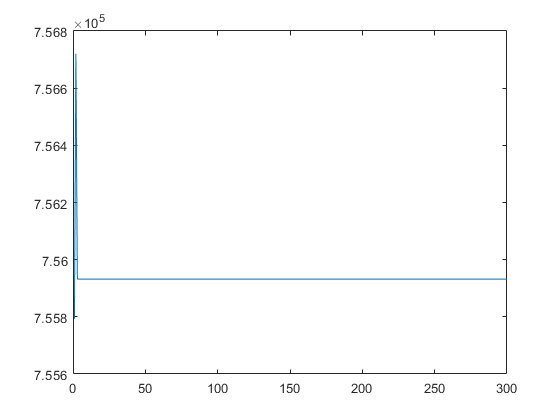

plot(TTS_history_5_1_1)

u_optimal_5_1_1=(u_optimal_5_1_1+2)*5

u_optimal_5_1_1 =     25    30    30    30    30    30    30    30    30    30    30    30    30    35    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    30    45    30    30    30    30    30    30    30    30    30


[TTS,y,x,z,m,s,u] = TTS_calculate(u_optimal_5_1_1(1),u_optimal_5_1_1(2:end));
x(1,:)

ans =          0   31.5000   37.8000   37.8000   37.8000   37.8000   37.8000   37.8000   37.8000   37.8000   37.8000   37.8000   37.8000   37.8000   37.8000   37.8000   37.8000   37.8000   37.8000   37.8000   37.8000   37.8000   43.4667   44.6000   44.6000   44.6000   44.6000   45.2367   46.8733   49.5100   53.1467   57.7833   63.4200   70.0567   78.4583   88.8600  101.2617  113.6633  126.0650  138.4667  150.8683  163.2700  177.5844  191.3260  205.0677  218.8094  232.5510  244.2927  254.0344  261.7760


x(2,:)

ans =          0   34.8333   34.8333   34.8333   34.8333   34.8333   34.8333   34.8333   34.8333   34.8333   34.8333   34.8333   34.8333   34.8333   36.2600   35.6033   34.9467   34.8333   34.8333   34.8333   34.8333   34.8333   34.8333   34.8333   34.8333   34.8333   34.8333   34.8333   35.6767   37.5200   40.3633   44.2067   49.0500   54.8933   61.7367   69.5800   78.4233   87.2667   96.1100  104.9533  113.7967  126.6350  131.9733  140.3267  149.1700  158.0133  166.8567  174.7000  181.5433  187.3867


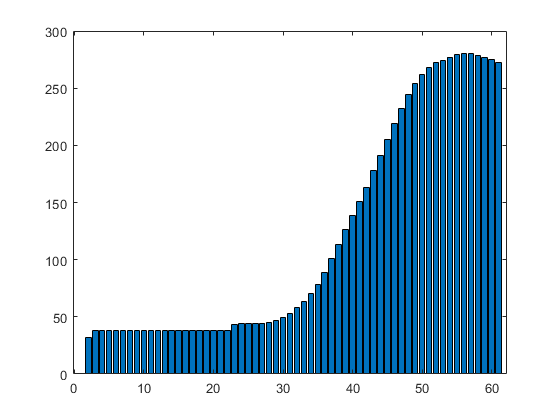

bar(x(1,:));


%iteration

function [u_optimal,TTS_min_history]=genetic_optimization(u0_generation,u_generation,u_options,...
    round,generation_round,member_number,mutation_probability,exchange_position,parents_number)
    %u_optimal for the optimal u(k),TTS_min_history for the TTS history

    u=ones(1,round);
    TTS_generation=ones(member_number,1);
    TTS_min=[];
    for i=1:1:generation_round
        for j=1:1:member_number
            u0=u_options(u0_generation(j));
            for k=1:1:round
                u(k)=u_options(u_generation(j,k));
            end
            TTS(j) = TTS_calculate(u0,u);
        end
        %sort TTS to find better parents
        sorted_TTS=sort(TTS);
        
        %specified better parents
        parents_position=find(TTS<=sorted_TTS(parents_number),parents_number);
        
        %calculate weight of parents
        w=zeros(1,member_number);
        w(parents_position)=sum(TTS(parents_position))./TTS(parents_position);
        w=w/sum(w);
        
        TTS_min=[TTS_min,min(TTS)];
        pos=find(TTS==min(TTS));
        u_optimal=u_generation(pos(1),:);
        
        %generation children
        children=[];
        for t=1:1:member_number/2
            parent_1=randsample([1:1:member_number],1,true,w);
            parent_2=randsample([1:1:member_number],1,true,w);
            
            %exchange
            child_1=[u_generation(parent_1,1:exchange_position),...
                u_generation(parent_2,exchange_position+1:end)];
            child_2=[u_generation(parent_2,1:exchange_position),...
                u_generation(parent_1,exchange_position+1:end)];
            
            %mutation
            for b=1:1:length(round)
                prob_1=rand(1);
                prob_2=rand(2);
                if (prob_1<=mutation_probability)
                    child_1(b)=randi(length(u_options));
                end
                if (prob_2<=mutation_probability)
                    child_2(b)=randi(length(u_options));
                end
            end
            
            %%add children to new generation
            children=[children;child_1;child_2];
                 
        end
        u_generation=children;
    end
    u_generation;
    TTS_min_history=TTS_min;
end
